% ------------------------------------------------------------
% Synthetic EEG generator for 4 datasets
%   Sets:
%     1: w=0.2, b=0, nLat=4
%     2: w=0.2, b=0, nLat=8
%     3: w=2,   b=1, nLat=4
%     4: w=2,   b=1, nLat=8
% ------------------------------------------------------------
clear; clc;
%% Generate Synthetic EEG Sets 1–4 with embedded 32-channel 10–20 coordinates
if exist('H:\', 'dir')
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\Shared Code';
elseif exist('G:\', 'dir')
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\Shared Code';
else
    error('Unknown system: Cannot determine input and output paths.');
end

outputDir = fullfile(output_path, 'simEEG');

% Create folder if missing
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end


## --- Create standard 32-channel 10–20 layout ----------------------------

% Your requested peak frequencies for latent generators
fpeak = [2 5 10 12 20 30 40 50];   % will truncate if nLatents < 8

% Labels in typical 32-channel systems (BioSemi 32 / EasyCap 32 style)
labels = {
    'Fp1','Fp2','F7','F3','Fz','F4','F8',...
    'FC5','FC1','FC2','FC6',...
    'T7','C3','Cz','C4','T8',...
    'TP9','CP5','CP1','CP2','CP6','TP10',...
    'P7','P3','Pz','P4','P8',...
    'PO3','O1','Oz','O2', 'PO4'
};

% Convert 10–20 positions to approximate 2D Cartesian coordinates
% (θ = azimuth, φ = elevation)
coords = zeros(32, 2);

thetaMap = containers.Map;
phiMap = containers.Map;

% approximate angles—keeps spatial structure very close to EEGLAB's 10–20
thetaMap('Fp1') = -72;  phiMap('Fp1') = 72;
thetaMap('Fp2') = 72;   phiMap('Fp2') = 72;

thetaMap('F7') = -90;   phiMap('F7') = 50;
thetaMap('F3') = -36;   phiMap('F3') = 50;
thetaMap('Fz') =   0;   phiMap('Fz') = 50;
thetaMap('F4') =  36;   phiMap('F4') = 50;
thetaMap('F8') =  90;   phiMap('F8') = 50;

thetaMap('FC5') = -72;  phiMap('FC5') = 30;
thetaMap('FC1') = -18;  phiMap('FC1') = 30;
thetaMap('FC2') =  18;  phiMap('FC2') = 30;
thetaMap('FC6') =  72;  phiMap('FC6') = 30;

thetaMap('T7') = -90;   phiMap('T7') = 0;
thetaMap('C3') = -36;   phiMap('C3') = 0;
thetaMap('Cz') =  0;    phiMap('Cz') = 0;
thetaMap('C4') =  36;   phiMap('C4') = 0;
thetaMap('T8') =  90;   phiMap('T8') = 0;

thetaMap('TP9') = -108; phiMap('TP9') = -20;
thetaMap('CP5') = -72;  phiMap('CP5') = -20;
thetaMap('CP1') = -18;  phiMap('CP1') = -20;
thetaMap('CP2') = 18;   phiMap('CP2') = -20;
thetaMap('CP6') = 72;   phiMap('CP6') = -20;
thetaMap('TP10')= 108;  phiMap('TP10')= -20;

thetaMap('P7') = -90;   phiMap('P7') = -40;
thetaMap('P3') = -36;   phiMap('P3') = -40;
thetaMap('Pz') = 0;     phiMap('Pz') = -40;
thetaMap('P4') = 36;    phiMap('P4') = -40;
thetaMap('P8') = 90;    phiMap('P8') = -40;

thetaMap('PO3') = -54; phiMap('PO3') = -60;
thetaMap('O1') = -36;   phiMap('O1') = -60;
thetaMap('Oz') = 0;     phiMap('Oz') = -60;
thetaMap('O2') = 36;    phiMap('O2') = -60;
thetaMap('PO4') = 54; phiMap('PO4') = -60;

% --- Convert to 2D Cartesian coordinates ------------------------------
for i = 1:32
    % Direct mapping based on your definitions:
    % theta = Left-Right axis (X)
    % phi   = Posterior-Anterior axis (Y)
    
    x = thetaMap(labels{i});
    y = phiMap(labels{i});
    
    coords(i,1) = x;
    coords(i,2) = y;
end

% Standardize orientation: 
% Ensure Nose is +Y (Up) and Right Ear is +X (Right)
% (Your data already follows this: Fp1 is +72(y), T8 is +90(x))

% center and normalize coords to unit circle (preserve aspect ratio)
coords = coords - mean(coords,1);               % center
coords = coords ./ max(sqrt(sum(coords.^2,2))); % scale so max radius = 1
coords = coords * 0.9;                          % leave margin                      % leave margin



## --- Simulation parameters ------------------------------------------------


Fs = 500;      % sampling rate
T  = 3.5;      % duration
t  = 0:1/Fs:T-1/Fs;

%% --- Loop over 4 datasets -------------------------------------------------
for setIdx = 1:4

    switch setIdx
        case 1
            w = 0.2; b = 0;  nLat = 4;
        case 2
            w = 0.2; b = 0;  nLat = 8;
        case 3
            w = 2;   b = 1;  nLat = 4;
        case 4
            w = 2;   b = 1;  nLat = 8;
    end

    nChan = 32;

    % spatial patterns
    S = randn(nChan, nLat);

% latent time series (Band-pass filtered noise)
    H = zeros(nLat, length(t));
    
    for j = 1:nLat
        fj = fpeak(j);
        
        % 1. Define a bandwidth for the "random" amplitude/phase effect
        %    (e.g., 2 Hz bandwidth or proportional to frequency)
        bw = max(fj * 0.2, 2.0); 
        
        % 2. Design a band-pass Butterworth filter
        %    (Normalize frequencies by Nyquist Fs/2)
        nyq = Fs / 2;
        Wn = [max(0.1, fj - bw/2), fj + bw/2] / nyq;
        [b_filt, a_filt] = butter(2, Wn);
        
        % 3. Generate white noise and filter it
        noise = randn(1, length(t));
        filt_noise = filtfilt(b_filt, a_filt, noise);
        
        % 4. Normalize to have unit variance (so peaks are roughly +/- 2)
        H(j,:) = filt_noise / std(filt_noise); 
    end

    % tanh mixture
    simEEG = zeros(nChan, length(t));
    for i = 1:nChan
        x = w * sum( S(i,:)' .* H, 1 ) + b;
        simEEG(i,:) = tanh(x);
    end

    % Save file -------------------------------------------------------------
    outFile = fullfile(outputDir, sprintf("simEEG_set%d.mat", setIdx));
    save(outFile, "simEEG", "S", "H", "t", "w", "b", "coords", "labels");
end



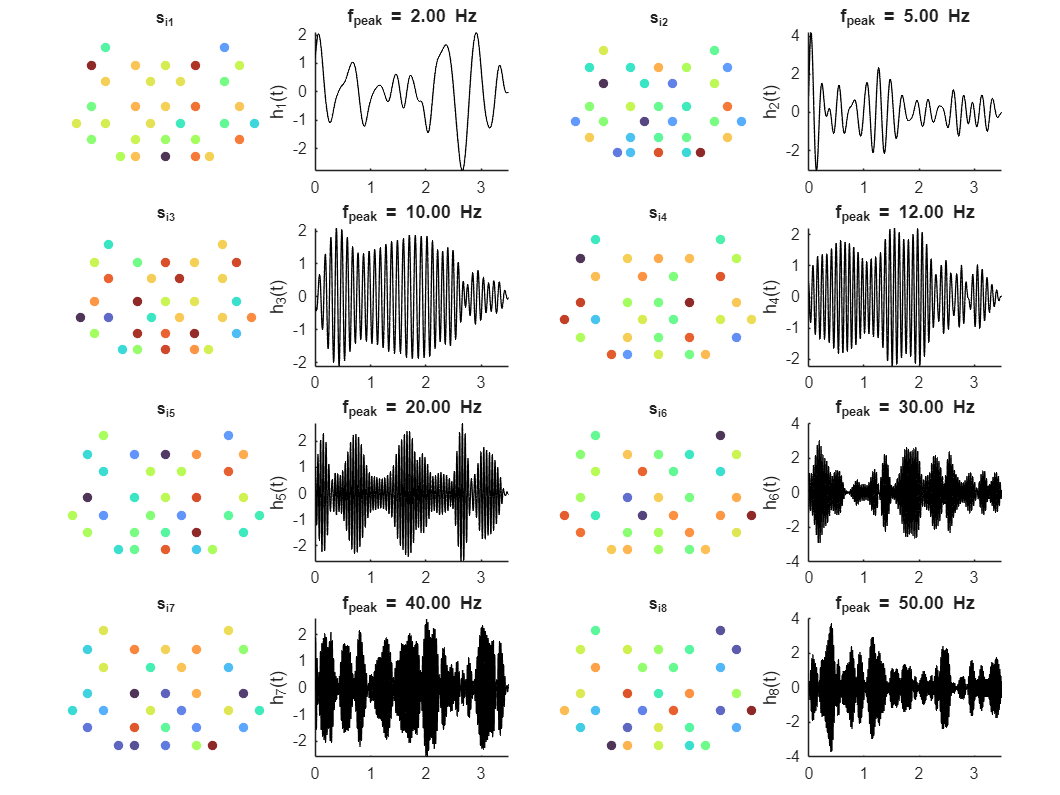

% ----------------------------------------------------------
% Inputs you must have:
%   S       : [nChannels x nLatents] spatial maps
%   H       : [nTime x nLatents] latent time series
%   coords  : [nChannels x 2] electrode (x,y) coordinates
%   fpeak   : [1 x nLatents] peak frequencies
% ----------------------------------------------------------

nLat = size(S, 2);      % number of latents (4 or 8)
t     = linspace(0, 3.5, size(H,2));   % assume 3.5 s duration


figure('Position', [50 50 1200 900]);
tiledlayout(nLat/2, 4, 'TileSpacing', 'compact', 'Padding', 'compact');

for k = 1:nLat

    % ------------------------
    % Left panel: spatial map
    % ------------------------
    nexttile;

    % Example plotting snippet for one component k:
    sk = S(:,k);
    sk = sk / max(abs(sk));   % normalize to [-1,1] for good color scaling
    
    markerSize = 50;         % reduce if still too crowded
    h = scatter(coords(:,1), coords(:,2), markerSize, sk, 'filled');
    % add transparency (MATLAB R2019a+ supports MarkerFaceAlpha)
    try
        h.MarkerFaceAlpha = 0.85;
    catch
        % older MATLAB: no MarkerFaceAlpha, leave as-is
    end
    colormap(turbo);
    axis equal off;
    title(sprintf('s_{i%d}', k), 'Interpreter', 'tex', ...
          'FontWeight', 'bold', 'FontSize', 12);

    % ------------------------
    % Right panel: time series
    % ------------------------
    nexttile;

    plot(t, H(k,:), 'k', 'LineWidth', 1);
    xlim([t(1), t(end)]);

    title(sprintf('f_{peak} = %.2f Hz', fpeak(k)), ...
          'Interpreter', 'tex', 'FontSize', 13);

    ylabel(sprintf('h_{%d}(t)', k), 'Interpreter', 'tex');

    set(gca, 'FontSize', 12, 'Box', 'off');
end